# RFID Antenna Design

This example creates a commercially available RFID tag operating at 915 MHz. The planar antenna is drawn and meshed using PDE Toolbox™. The meshed structure is then imported into Antenna Toolbox and solved for its EM properties.

This example requires the following product:

- Partial Differential Equation Toolbox™

## RFID Antenna

Below is a commercially available RFID antenna. These tags are typically used on boxes for inventory tracking. The main requirement for these tags is that they should be cheap to manufacture and have a very narrow band. The antenna below has an overall dimension of 22 mm x 22 mm.

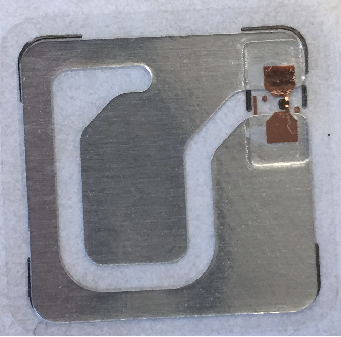

**Fig.1: RFID antenna tag.**

## Drawing the Antenna Geometry

The antenna geometry can be drawn using pdetool in PDE Toolbox. The pdetool provides a graphical user interface to draw and mesh a 2D geometry. Call pdetool without arguments to start the application. The figure below is the snapshot of the pdetool with a basic layout of the antenna. Rectangle R1 is used to create the 22 mm square. Various slots in the structure are created using rectangles R2 to R5 as shown below. The rectangles R5 can be connected to R6 using a polygon shape. Similar idea can be used to connect R2 with R3.

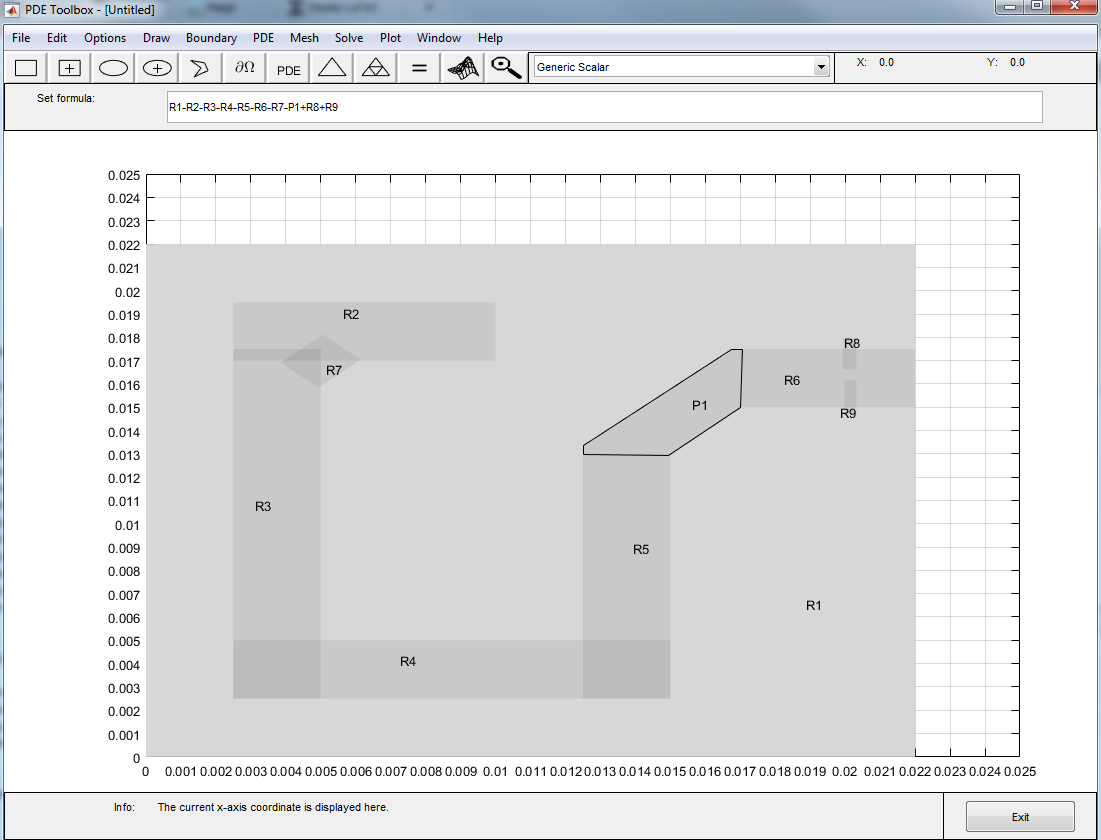

**Fig.2. Geometry layout of the antenna tag.**

Once the desired antenna geometry is set up, Boolean operations can be performed on the various shapes. In this example, the rectangles R2 to R7 need to be subtracted from the rectangle R1 to create the slots. The two rectangles R8 and R9 are added so that the antenna can be fed between them. The Boolean operation can be performed in the Set formula tab.

## Meshing the Antenna

Once the Set formula tab is filled with the correct Boolean operation, press the triangle button, to mesh the structure. Maximum edge length in the mesh can be modified by setting the Max edge size value under Mesh->Parameters tab. The mesh below is generated with a maximum edge length of 2 mm.

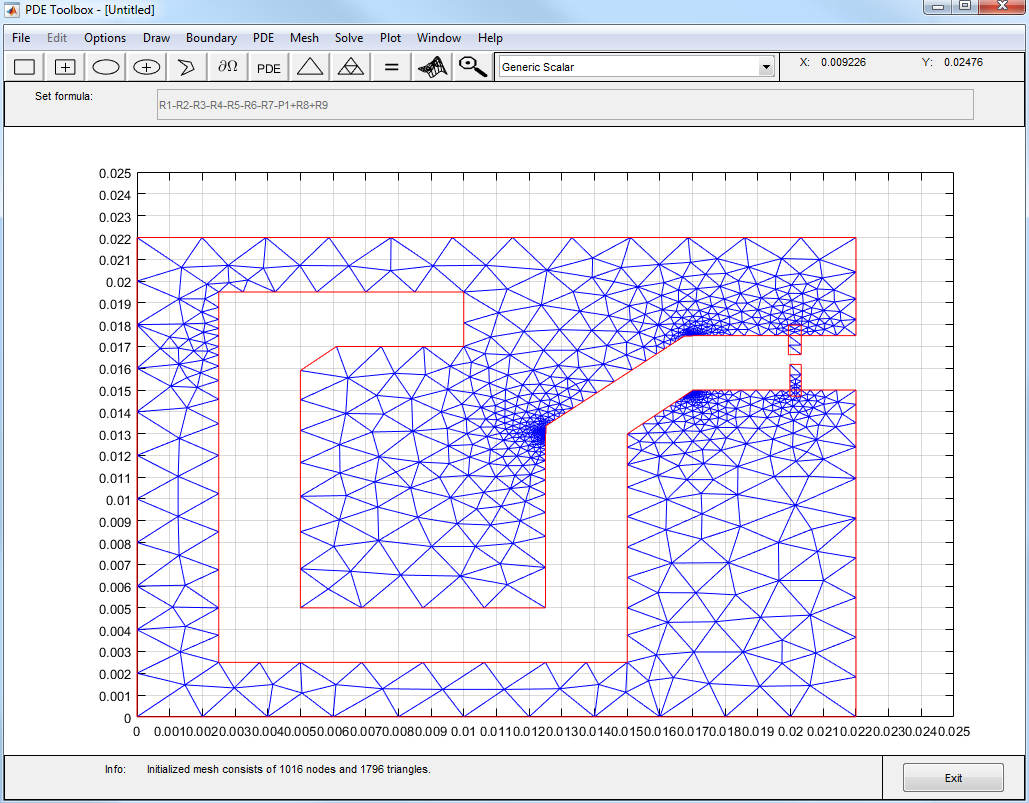

**Fig.3. Meshed antenna tag**

The generated mesh can be exported to the MATLAB workspace by selecting the Mesh-> Export Mesh tab. The p (Points), e (boundary edges) and t (triangles) are exported to the workspace. The data is saved in the file RFIDtag.mat. The complete antenna geometry is saved in the file RFIDtag.m.

## Creating a Custom Antenna

A custom planar mesh can be imported into Antenna Toolbox using the [customAntennaMesh](docid:antenna_ref#bvd8l0r-1) function. To convert this mesh to an antenna, a feed needs to be defined. This determines where the antenna is excited.

load RFIDtag
ant = customAntennaMesh(p, t);

The feed can be created by using a GUI or by specifying the two points across which the feed is defined. We will look at both these approaches in this example. Calling [createFeed](docid:antenna_ref#bux2yxy-1) with just the antenna as the input parameter opens the feed creating GUI.

createFeed(ant)

Pick a gap in the metal to feed the antenna. The interactive figure allows to select two triangles across the gap. Click the pick button which provides a cross hair to pick the two triangles. The figure below shows the way to select the first triangle. Bring the cross hair over the triangle as shown below and press the left mouse button.

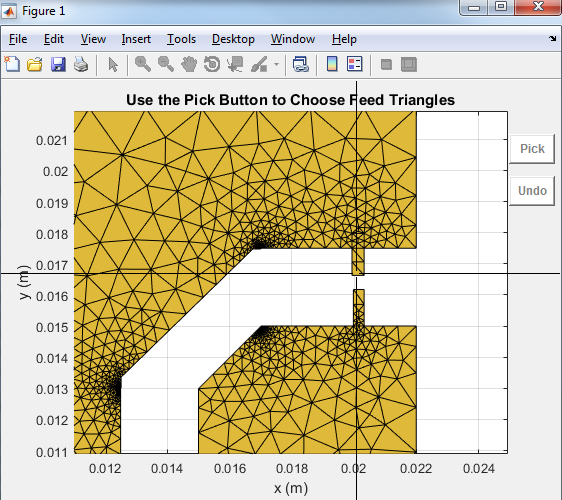

Repeat the process for the second triangle across the gap. Once the two feed triangles are selected the figure will update to show the feed with green triangles as shown below. The red dot shows the feeding edge. To change the feed location, click the undo button and start again.

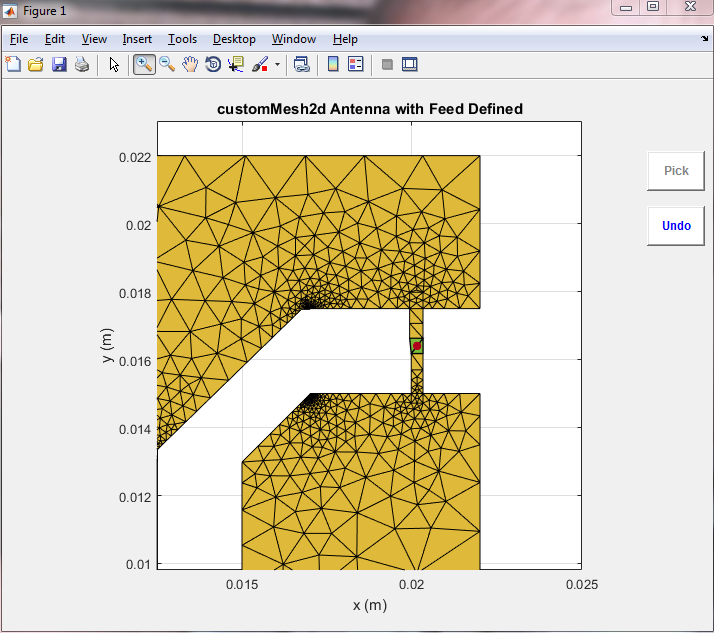

The other way to create the feed is by specifying the two points between which the feed needs to be created as shown below. Use the [show](docid:antenna_ref#bukkic2-1) function to visualize the antenna.

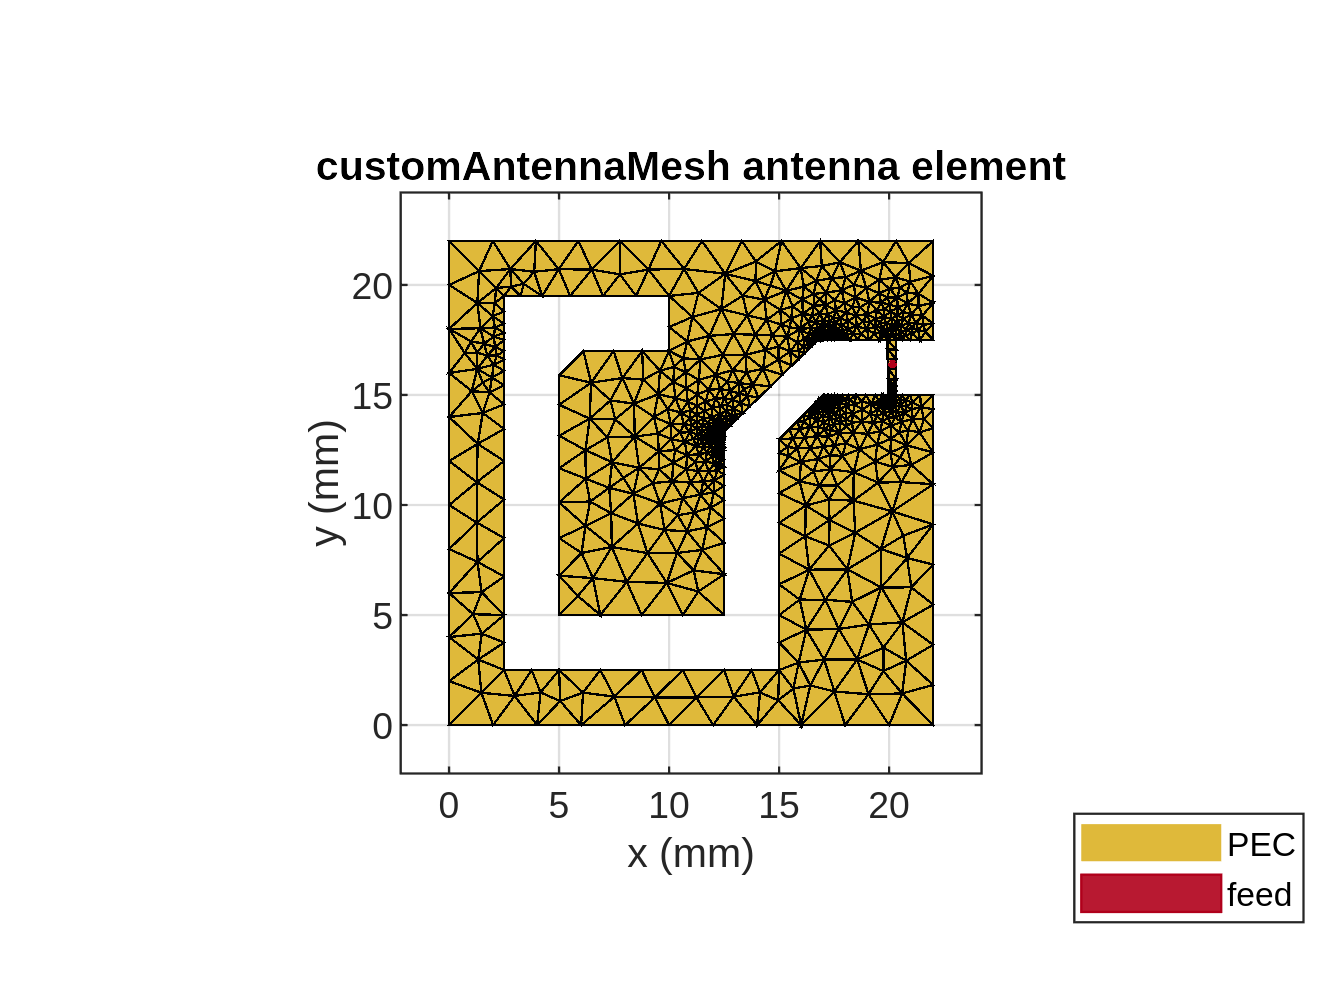

createFeed(ant, [0.0201 0.0168], [0.0201, 0.0161]);
show(ant);
view(2);

## Impedance of the RFID Antenna

The custom antenna can now be solved by calling all the analysis functions of the Antenna Toolbox. We are interested in the operation of the RFID tag at 915 MHz.

z = impedance(ant, 915e6)

z = 7.0565e-01 + 2.9162e+02i

The impedance values above indicate that the antenna is highly inductive with a small resistance value. This is typical for RFID tags. A matching network at 915MHz need to be designed for successful operation of the tag.

More information on designing a matching network can be obtained in the following demo. [Impedance Matching of a Non-resonant(Small) Monopole](docid:antenna_ug#example-ex69883049);

## Radiation Pattern of the RFID Antenna

The directivity of the RFID antenna is shown below. The tag has a null at the zenith but good coverage in the x-y plane and a maximum value of about 1.5dBi. This shows that the antenna is operational over a short distance from the reader, which is a requirement for an RFID tag.

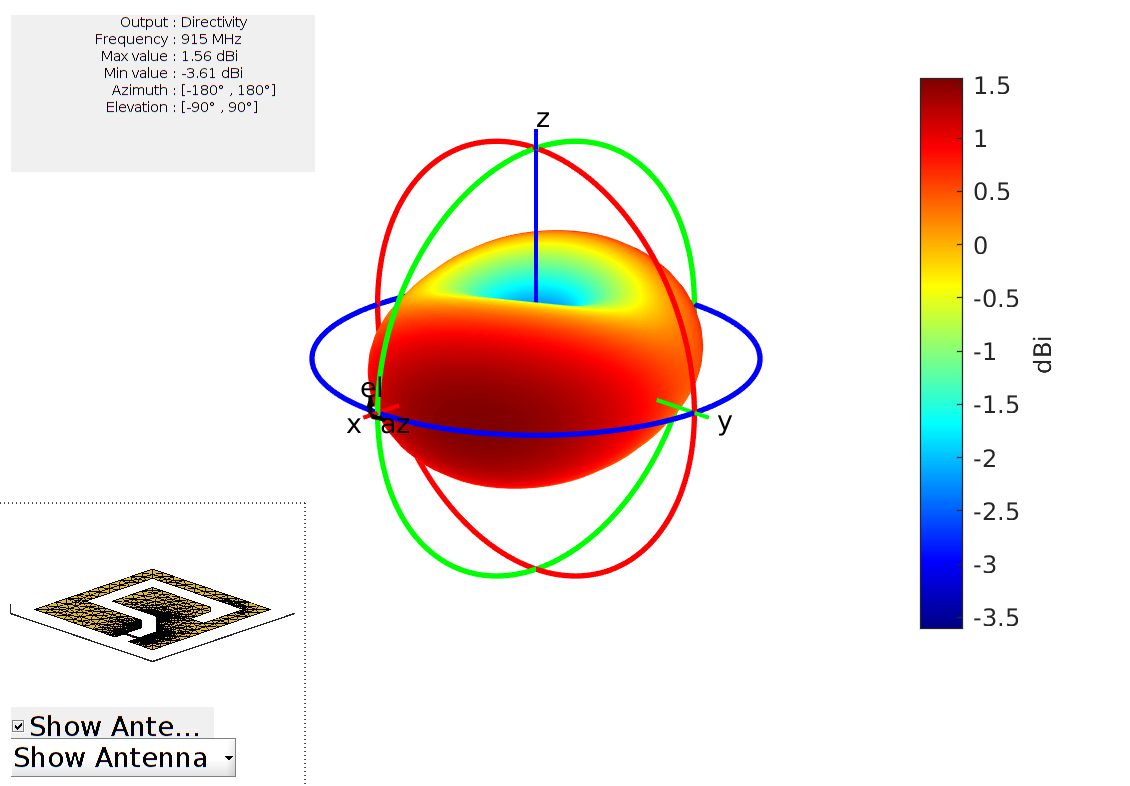

pattern(ant, 915e6);

*Copyright 2015 The MathWorks, Inc.*